# Modism Project 3 - 1A

## Question

On November 24th, 2021, a spacecraft named DART was launched. Its mission is to fly itself into an asteroid to test out weather such an impact could be a feasible method to redirect an earth-threating object. 

In this model, we are **predicting** weather DART would have been able to redirect the Chicxulub impactors (the asteroid hypothesized to have led to the dinosaur extinction) and if so, how many years in advance would DART need to collide to produce a safe trajectory. 

This is an interesting question because it might demonstrate that humans have power to influence cosmic phenome that would otherwise lead to human extinction. Additionally, it could highlight what areas of research are necessary to make DART be effective against larger asteroids.

## Method

We will begin by developing a 2d model of our system. The earth is placed statically at the origin while the Chicxulub asteroid is free to move around according got Newtonian physics.

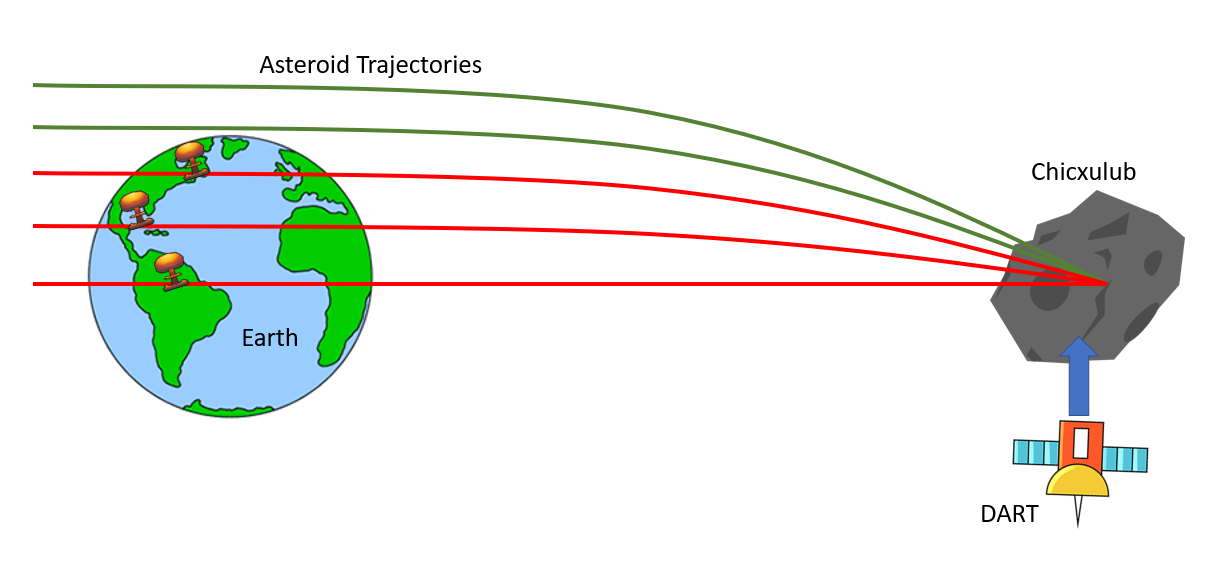

We will use the equation for standard gravitation to determine the motion of the asteroid.


$$\frac{d^2x}{dt^2} = -G\frac{m_{earth}}{x^2}\hat{r}$$


- Where $\hat{r}$ is a unit vector that points from the center of the asteroid to the origin (center of earth).

This system can be decomposed into the following first order system:

- 
$$\frac{dv}{dt} = -G\frac{m_{earth}}{x^2} \hat{r}$$


- 
$$\frac{dx}{dt} = v$$


We will need position and velocity data for the Chicxulub asteroid however this data is not widely available. What we do have access to are the final conditions of the asteroid (position, speed, and impact angle) which means we can run our model “backwards” to simulate what the Chicxulub trajectory might have looked like. We do this by setting the initial conditions of the model to the “final conditions” of the asteroid, remembering to multiply the initial velocity and the gravity equation by -1. Then we run the model “backwards” for as long as we need in order to generate the necessary position and velocity data.

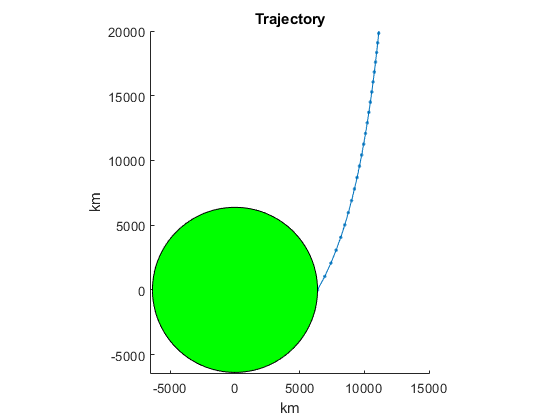

global year2sec
year2sec = 364.25 * 24 * 3600;

years = 0.01 * year2sec;
chic_data = chicxulub(years, 100);  %generate data for the asteriod for 0.01 years at 0.001 hour timesteps
plot_traj(chic_data); %plot the trajectory
axis([-6500 15000 -6500 20000])

max_time = 5*365*24;
dt = 1;
path = chicxulub(max_time, dt); % calculate the trajectory of the impactor

This graph shows the first (or last depending on how you think about it) few datapoints from the reconstructed trajectory.

When the DART spacecraft collides with the asteroid, we will use conservation of momentum to find the new velocity of the asteroid at the time of collision. This momentum transfer is government by the following equations:

- 
$$P_{chic} + P_{DART} = P_{comb}$$


- 
$$m_{chic}v_{chic} + m_{DART}v_{DART} = m_{comb}v_{comb}$$


- 
$$v_{comb} = \frac{m_{chic}v_{chic} + m_{DART}v_{DART}}{m_{comb}}$$


Initial testing revealed that even if the DART impact was a thousand years before earth impact, the trajectory would not be altered significantly. While this might be semi-realistic, there is some error involved with using both very large and very small numbers. The change in angle of the velocity after DART impact is so small that it cannot be correctly computed with ordinary double precision floating point number. For the sake of generating results, we opted to increase the mass of DART from 500kg to 1e11 kg just so that we might see a difference in a more measurable timeframe.

Iteration: In our initial model, we chose an arbitrary trajectory for the Chicxulub impactor where it crashes directly into the Earth. However, we did some research and found the real impact angle and then created a function that calculates a more-realistic trajectory for the impactor. In the first iteration of our model, we parameter-swept the distance from the Earth at which the DART collides with the impactor. In this current interation of our model, we parameter-sweep the time at which the DART collides with the impactor, where the position is determined using the impactor's calculated trajectory

## Results

max_time = 4*year2sec;
dt = 100;
chic_data = chicxulub(max_time, dt); % calculate the trajectory of the impactor

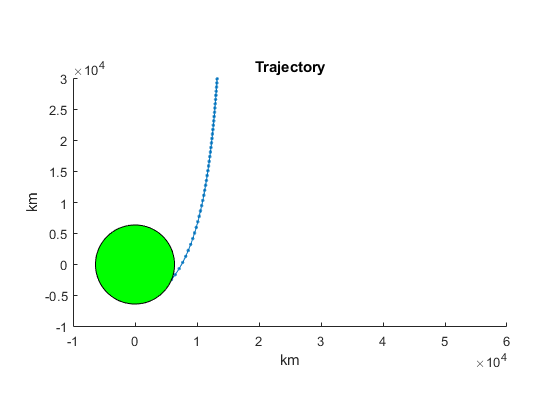


[t, d, i] = trajectory(year2sec * 0.5, dt, chic_data);
plot_traj([t d])

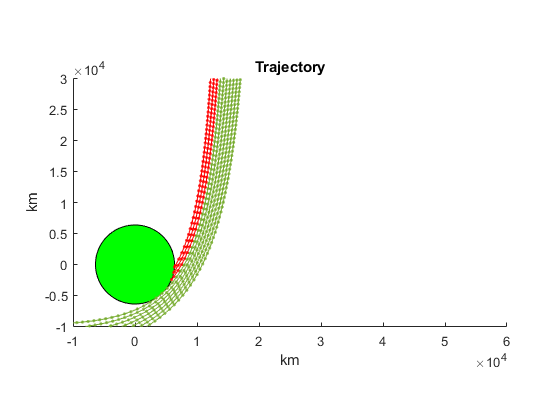


dt = 100;
t_range = year2sec * 0.1 : year2sec * 0.2 : year2sec * 2;
impacts = zeros(2, length(t_range));
figure
    clf
    x = linspace(0,2*pi,100);
    y = linspace(0,2*pi,100);
    x = 6378*sin(x);
    y = 6378*cos(y);
    
    
    
    hold on
    patch(x, y, "green")
    

for i=1:length(t_range)
    [t, X, impact] = trajectory(t_range(i), dt, chic_data); % if DART hits at max_time-i, will the impactor impact?
    impacts(1,i) = ~isempty(impact);
    impacts(2,i) = min(vecnorm(X(:,1:2)'));
    if isempty(impact)
        plot(X(:, 1)/1000, X(:, 2)/1000, ".-", "Color", [0.4660 0.6740 0.1880], "LineWidth", 0.5, "MarkerSize", 5)
    else
        plot(X(:, 1)/1000, X(:, 2)/1000, ".-r", "LineWidth", 0.5, "MarkerSize", 5)
    end
end
    
    xlabel("km")
    ylabel("km")
    title("Trajectory")
    axis equal
    axis([-10000 60000 -10000 30000])
    hold off

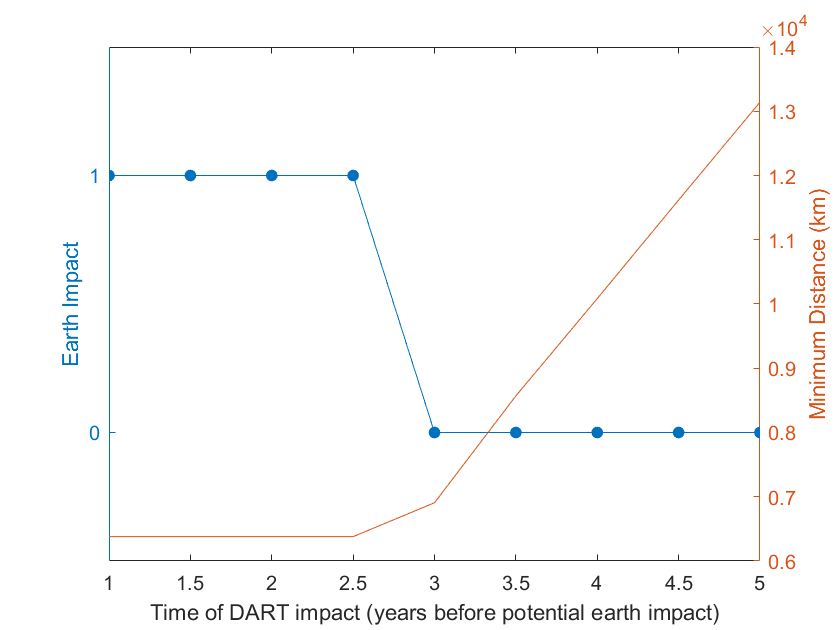

figure
clf
yyaxis right
plot(t_range / (365*24), impacts(2,:))
ylabel("Minimum Distance (km)")

yyaxis left
plot(t_range / (365*24), impacts, ".-", "Markersize", 20)
xlabel("Time of DART impact (years before potential earth impact)")
ylabel("Earth Impact")
ylim([-0.5 1.5])
yticks([0 1])

This shows that the 100 Teragram DART would have had to collide with the impactor at least 3 years in advance in order to deflect it enough as to not hit the earth.

## Interpretation

Theses initial results show that if we were able to launch a rocket that weighs 0.2 million times as much as the real DART spacecraft, we would only need to impact the Chicxulub asteroid three years in advance in order to redirect it safely away from earth.

In the next iteration of our model, we are considering adding a third body (the sun) as well as making some optimizations so that we can run our model with a realistic DART mass.